%%this is the preliminary function to create our spectral 
%analizer. We will be using MATLAB's built in code for fft and
%so forth to do the implementation of this.


%sets the basic parameters of frame size and sample rate of the system
SampleRate = 48000;
FrameSize = 1024;
NumChannels = 1;


%sets the fundamental frequency
fundamentalFrequency = SampleRate/FrameSize;


%sets the limits of the plot
x_lower = 0;
x_upper = SampleRate/2;
y_lower = 0;
y_upper = 40;


%sets up the audioReader object
audioReader = audioDeviceReader('NumChannels',NumChannels, ...
    'BitDepth','24-bit integer', ...
    'SamplesPerFrame',FrameSize, ...
    'SampleRate',SampleRate);

%sets up the audio writer
audioWriter = audioDeviceWriter('SampleRate',SampleRate, ...
    'BufferSize', FrameSize, ...
    'BitDepth', '24-bit integer');

%this starts the recording of the data
disp('Starting Processing');

Starting Processing


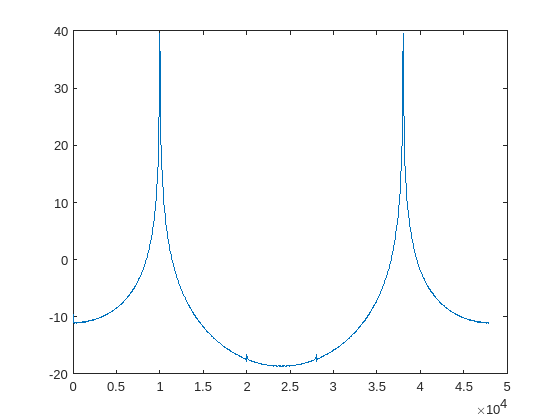




while 1
    
    %gets the audio data of one frame
    inputData = step(audioReader);
    
    %gets the FFT of the input data for the one frame, of length 1024
    inputDataFFT = fft(inputData);

    %gets the power of the inputDataFFT
    inputDataFFTPower = real(inputDataFFT).*real(inputDataFFT) + imag(inputDataFFT).*imag(inputDataFFT);
    
    %creates the space to go from zero hertz up to the sample rate
    x = linspace(0, SampleRate, FrameSize);

    %does the same plot, but now in dB
    plot(x,10*log10(inputDataFFTPower + 0.001));
    hold on;
    title("Power in dB");
    xlabel('Frequency (Hz)');
    ylabel('Power (dB)');
    %limits x to half the samplingfrequency for nyquist
    xlim([x_lower x_upper]);
    ylim([y_lower y_upper]);
    drawnow limitrate
    hold off;

    
    %outputs the just processed audio data to the writer
    step(audioWriter, inputData);
    
    
end